# Piecewise Polynomial Interpolation: Introduction

## Polynomial Interpolation: Effect of Node Distribution

Let's interpolate the following data:

n = 15;
f = @(x) 1./(1+25*x.^2);

### Polynomial interpolation: Equispaced nodes

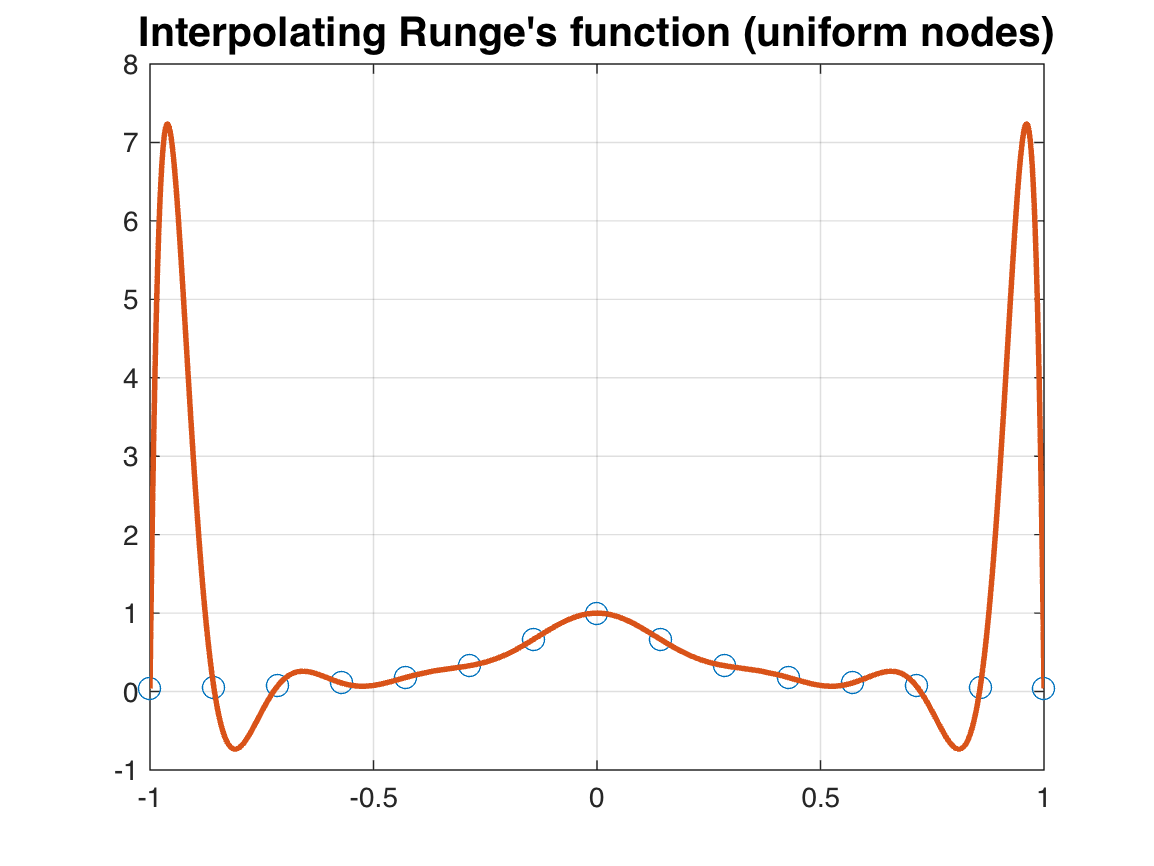

xdp = linspace(-1, 1, n)';
ydp = f(xdp);
c = polyfit(xdp, ydp, n-1);
p = @(x) polyval(c, x);
% The two lines above accomplish the same task as below
%   V = x.^(0:n-1);   
%   c = V\y;
%   p = @(x) polyval(flip(c),x);

clf
plot(xdp, ydp, 'o', 'MarkerSize', 8)
title('Interpolating Runge''s function (uniform nodes)', 'FontSize', 15)
grid on, hold on
fplot(p, [-1 1], 'LineWidth',2)
xlim([-1 1])

% print -depsc 'interp_unif'

Note the large oscillations, well beyond the data points, near the endpoints. This is called the **Runge's phenomenon**.

### Polynomial interpolation: Special nodes (Chebyshev nodes)

The situation is mitigated if nodes are clustered near endpoints. A set of Chebyshev nodes is one such example.

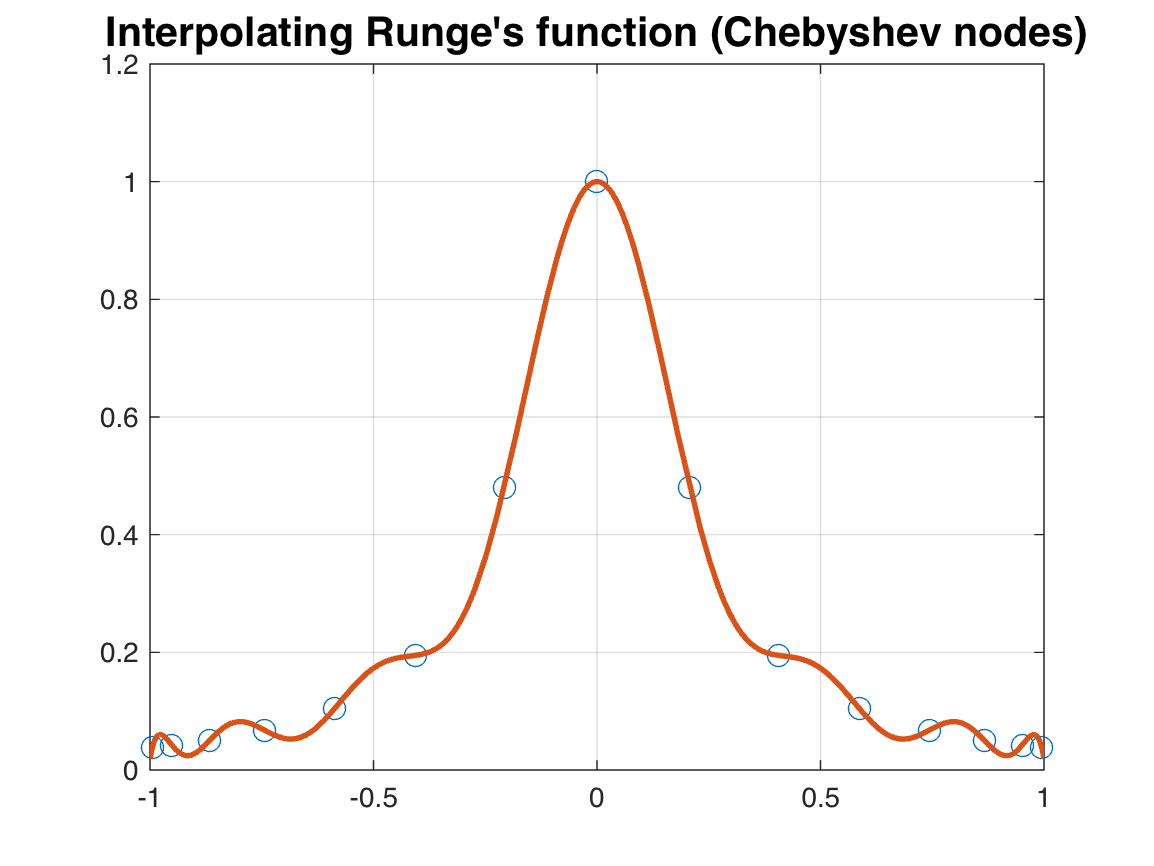

t = linspace(0, pi, n+1);
t(end) = [];
t = t + (t(2)-t(1))/2;
xdp = -cos(t);
ydp = f(xdp);
c = polyfit(xdp, ydp, n-1);
p = @(x) polyval(c, x);

clf
plot(xdp, ydp, 'o', 'MarkerSize', 8)
title('Interpolating Runge''s function (Chebyshev nodes)', 'FontSize', 15)
grid on, hold on
fplot(p, [-1 1],'LineWidth',2)
xlim([-1 1])

% print -depsc 'interp_cheb'

## Piecewise Interpolation using `INTERP1`

Generate data again. 

xdp = linspace(-1, 1, n)';
ydp = f(xdp);
x = linspace(-1, 1, 400)';

### Piecewise linear interpolation

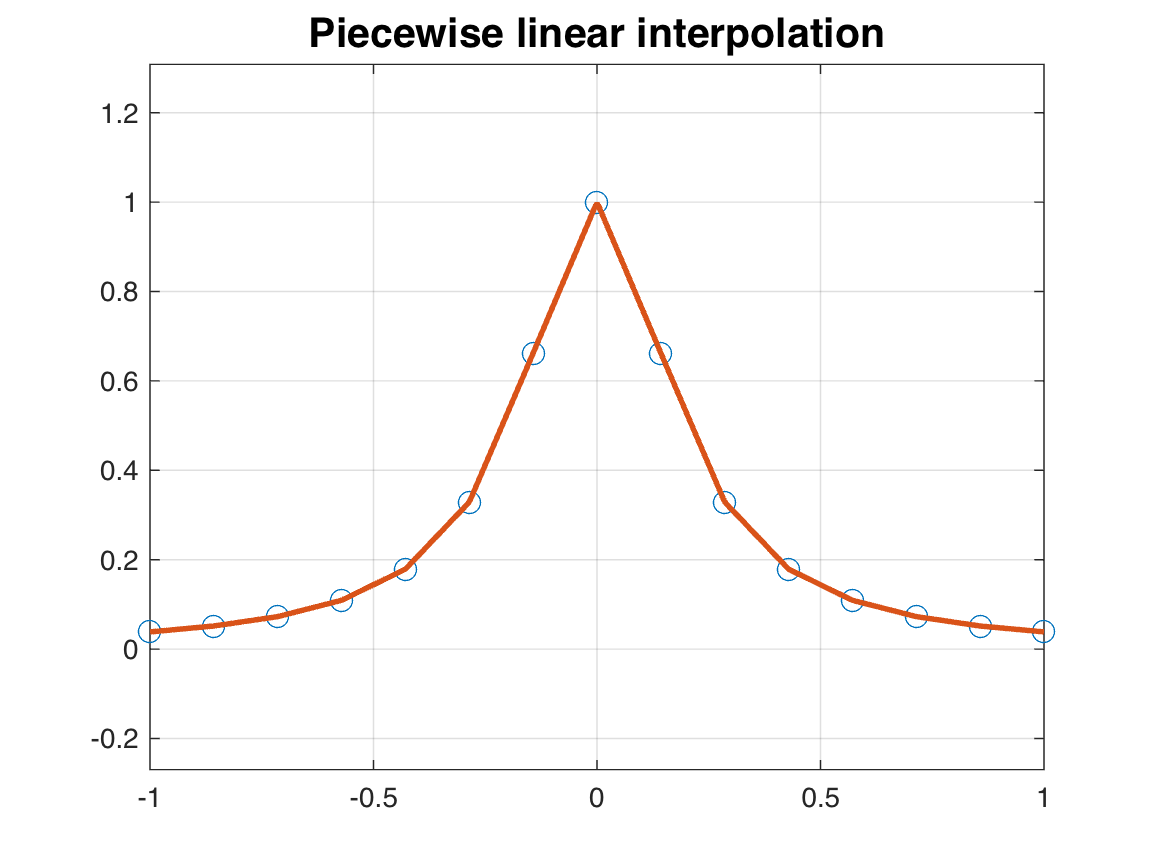

clf
plot(xdp, ydp, 'o', 'MarkerSize', 8)
hold on
plot(x, interp1(xdp, ydp, x), 'LineWidth', 2)
title('Piecewise linear interpolation', 'FontSize', 15)
grid on, axis equal

% print -depsc 'plinterp'

### Cubic spline

This is the most commonly used piecewise cubic interpolation. 

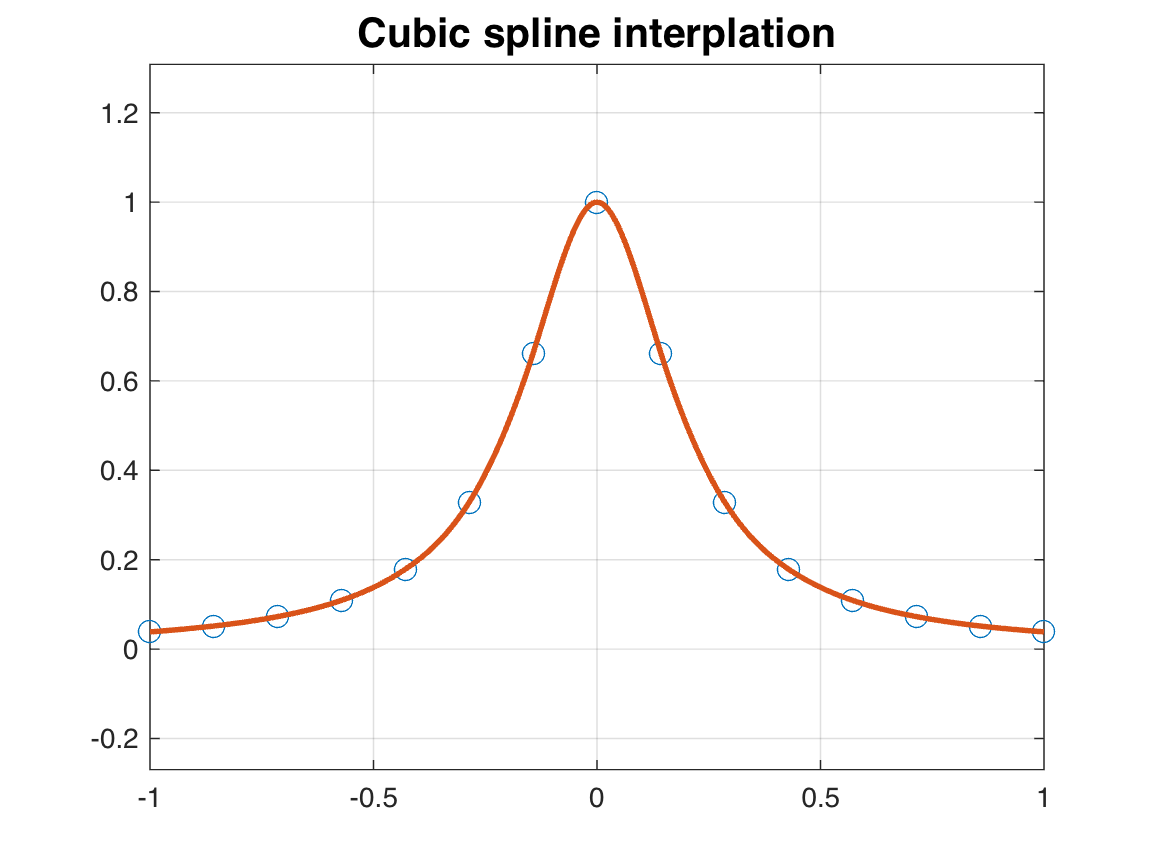

clf
plot(xdp, ydp, 'o', 'MarkerSize', 8)
hold on
plot(x, interp1(xdp, ydp, x, 'spline'), 'LineWidth', 2)
title('Cubic spline interplation', 'FontSize', 15)
grid on, axis equal

%print -depsc 'splinterp'

## Conditioning and Cardinal Functions

Let's generate data corresponding to a cardinal function.

n = 17;
xdp = linspace(-1, 1, n)';
ydp = zeros(size(xdp));
ydp(8) = 1;   % 9th cardinal function
x = linspace(-1, 1, 400)';

### Piecewise cubic polynomial

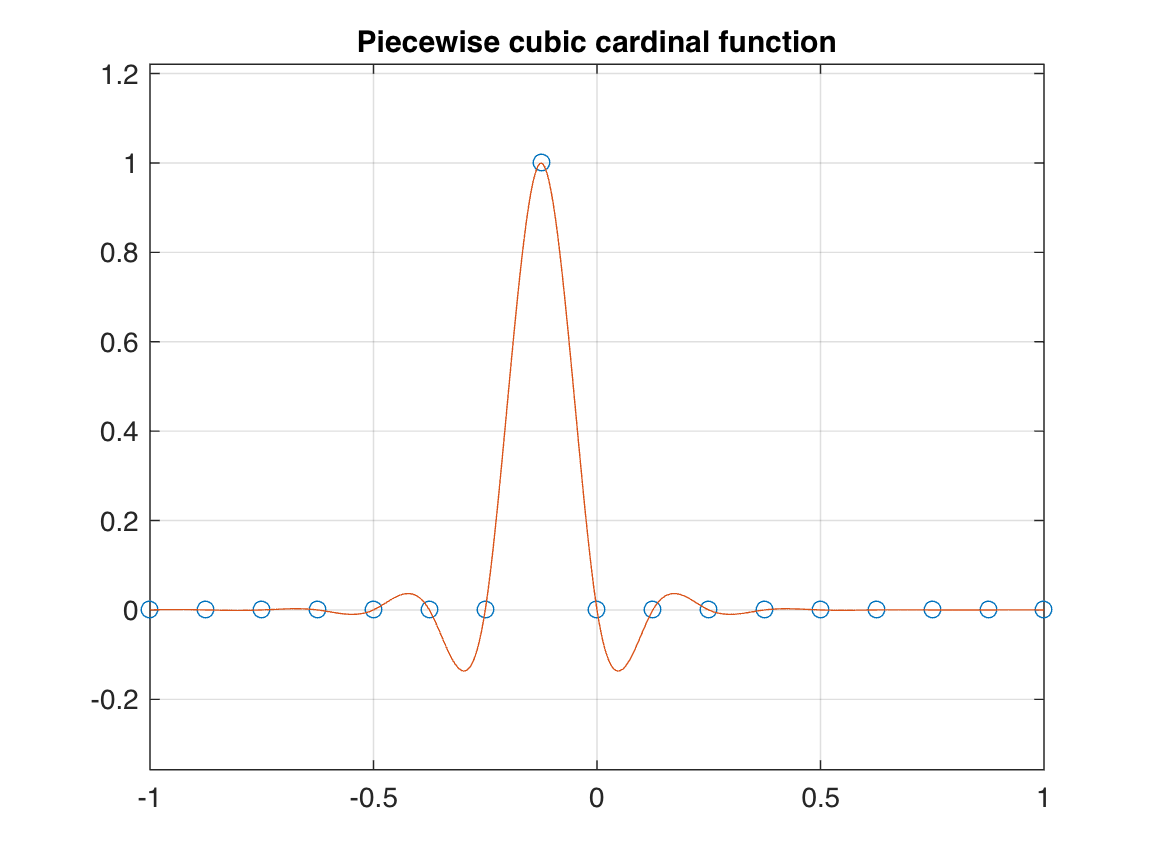

clf
plot(xdp, ydp, 'o')
hold on
plot(x, interp1(xdp, ydp, x, 'spline'))
grid on, axis equal
title('Piecewise cubic cardinal function')

Note that this piecewise cubic cardinal function is nowhere greater than 1 in magnitude. This happens to be true for all the other cardinal functions, which guarantees a small condition number for the interpolation. 

### Polynomial 

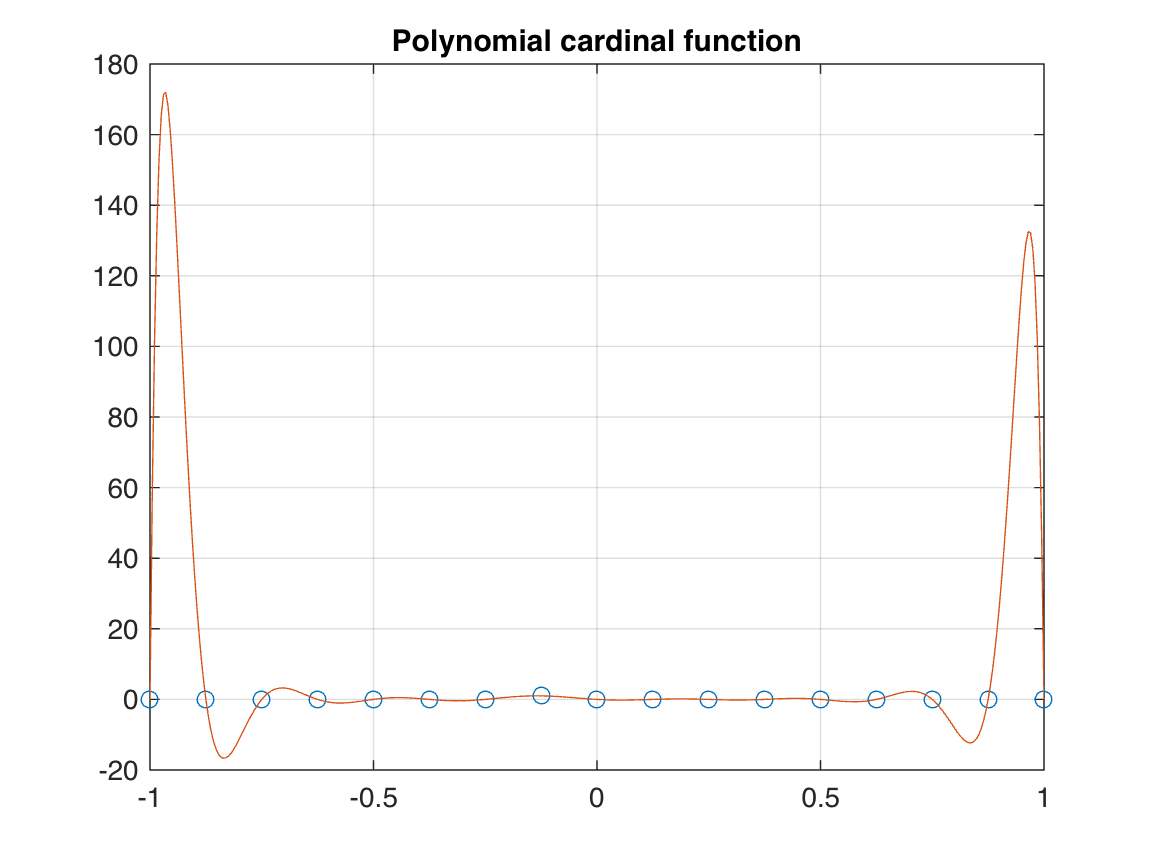

clf
plot(xdp, ydp, 'o')
hold on
plot(x, polyval(polyfit(xdp, ydp, n-1), x))
grid on
title('Polynomial cardinal function')

This is a degree-16 cardinal polynomial and its infinity norm is about 170. According to the theorem in lecture, the condition number for polynomial interpolation on these nodes is at least 170.